# 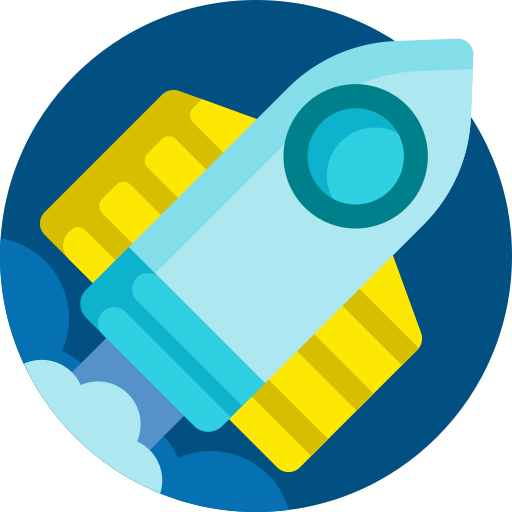 

# **MEC3079S: Control Systems**

# Chapter 8 — Feedback control systems

## 8.1 Introduction

This Chapter will introduce you to the feedback control systems and begin to highlight the powerful benefits of closed-loop configurations. So far we have only considered systems that are in an open-loop configuration when assessing stability and performance (e.g. peak time, settling time, frequency of oscillation). We will make use of many of these concepts when assessing closed-loop configurations, but we must first begin by understanding when feedback control is necessary and why.

### 8.1.1 Open-loop and closed-loop configurations

A block diagram representation of an open-loop system is shown in the left figure below. 

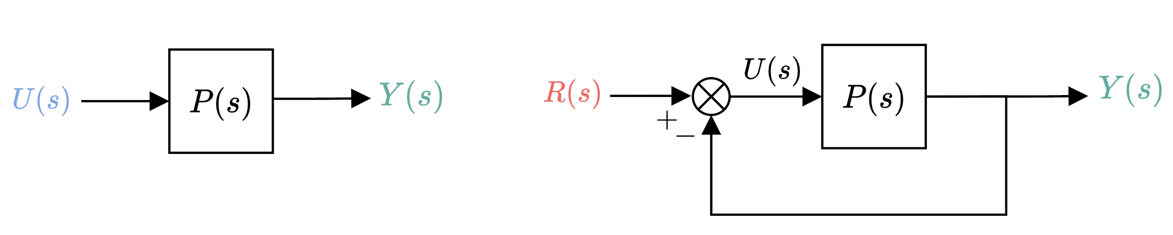

In an open-loop configuration, the input signal, $U(s)$, is independent of the output signal, $Y(s)$. In other words, no information about how the system is responding is being communicated with the input signal (it is in effect acting "blindly"). A simple closed-loop configuration on the right shows a different story. Here, output information is being fed back to the input (in this case using negative feedback). As a result, $U(s)$ will change depending on the value of $Y(s)$. This is a simplistic but apt view of the principle of feedback — that the observed behaviour of plant output of interest can be used to inform our input signal how to be adjusted, in order to eventually achieve some predefined control objective. 

### 8.1.2 Control action

In both the open-loop and closed-loop configuration we are able to directly or indirectly dictate how $U(s)$ behaves, with the hopes that this makes $Y(s)$ behave in a manner that we desire. We refer to $u(t)$, and by extension, $U(s)$, as the **control action **(or control signal). This signal is something that we will eventually determine using a feedback controller, with the objective of meeting all of our system specifications.

One thing to keep an eye on when analysing a closed-loop system is the behaviour of $u(t)$. In any real-world system, there will be strict limits on $u(t)$. We are primarily concerned with saturation limits of the form

$u_{min} \leq u(t) \leq u_{max}$,

where the control action is bounded above and below by some constant values. For example, we are only able to apply a finite amount of voltage to a motor in order to create rotational motion, which will be based on the power supply and rating of the various hardware elements. The control action is often also subject to rate limits of the form

$\dot{u}_{min} \leq \dot{u}(t) \leq \dot{u}_{max}$.

For example, if our control action is the flow rate of water into a tank, we cannot instantaneously go from zero flow rate to some non-zero quantity when opening and closing a valve. Instead, there will be some hard limit, related to the mechanical properties of the valve, that dictates how the flow rate increases. 

The two sets of constraints will cause the system to behave nonlinearly when any of the above limits is reached (e.g. $u(t)>u_{max}$). For this reason, when dealing with the Laplace transformed control action, $U(s)$, it can be easy to lose sight of the above constraints as it does not reflect when assuming the system is linear time-invariant. We must therefore be mindful of the control action required when analysing and design a control system. For now, we should try and keep $u(t)$ suitably small when doing a real-world design. While the focus of this course is not on control action minimisation, the subsequent sections will provide, in part, an indirect framework for encapsulating this aspect.

## 8.2 Purpose of feedback control

Before embarking on a feedback control design, we need to identify the reason(s) for requiring feedback. This is because a feedback system has additional tangible expenses, such as:

- Sensor cost(s),

- Controller hardware (analogue or digital),

- Engineering time and effort.

The three predominant reasons to implement a feedback controller are:

- Regulation - to reduce the effect of unmeasured disturbances on the system output.

- Tracking - to reduce the effect of plant uncertainty (including nonlinearity) on the reference to output behaviour.

- Stability - to stabilise an open-loop unstable system (required for regulation and tracking problems).

We will explore item 1 and 2 in this chapter, with the assumption that the system is closed-loop stable. Closed-loop stability is considered in detail in **Chapter 9**. If our open-loop system does not require intervention, then we need not bother going to the effort of designing a feedback controller. This will ultimately come down to the performance specifications that are outlined on the desired system, as well as the inherent properties of the open-loop system.

## 8.3 Analysing closed-loop configurations

### 8.3.1 The two-degree-of-freedom closed-loop control system

The block diagram below represents a generalised control system. External signals entering the control system are:

- $R(s)$, representing the reference signal (how we want our output $Y(s)$ to behave ideally),

- $D(s)$, representing a disturbance at the plant input (an immeasurable, uncontrollable signal acting on our system),

- $N(s)$, representing sensor noise (also generally considered as having zero mean with dominant high-frequency components).

Note that under special cases, a disturbance can also act at the plant output. However, we will not consider this scenario in this course.

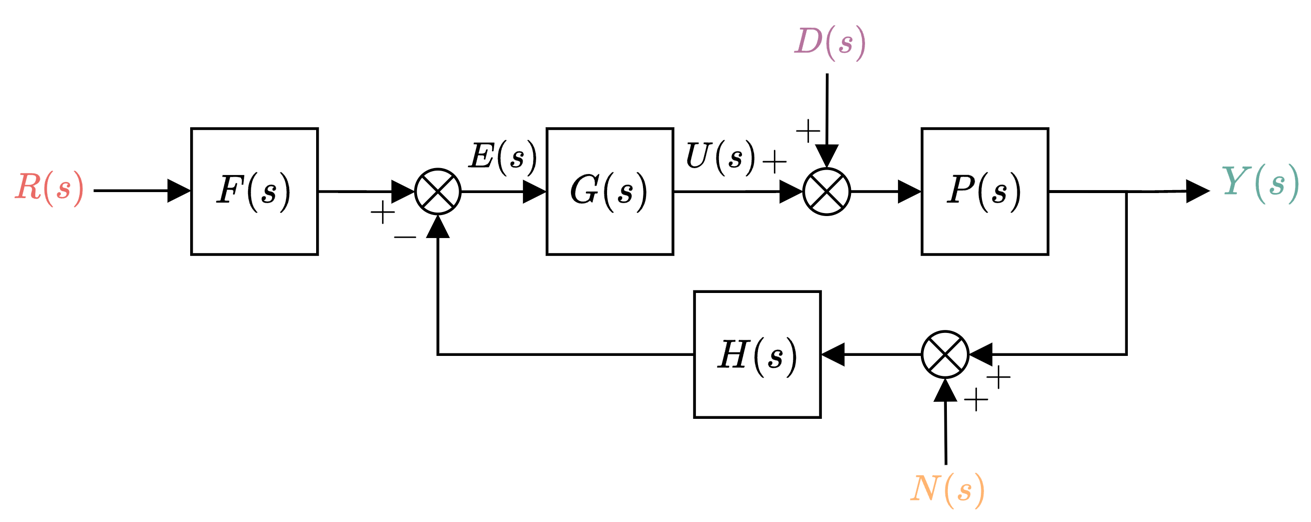

The control system's output of interest is denoted with $Y(s)$, which is the signal that we are trying to control. The system blocks within our control system collectively shape our control system structure, where

- $F(s)$ is a pre-filter to filter the reference $R(s)$ as required,

- $G(s)$ is our feedback controller,

- $P(s)$ is our plant under consideration, and

- $H(s)$ either represents sensor dynamics, or a filter that we have placed in the feedback loop (usually to deal with the effect of the noise, $N(s)$).

Importantly, we usually have no way of altering $P(s)$ — it is a system that is given to us and we must accept it warts and all. However, we have the ability to alter $G(s)$ and $F(s)$, and to some extent, $H(s)$.

A feedback control system is said to be a **two-degree-of-freedom system** when the forward transfer function from $Y(s)$ to $U(s)$, ignoring the sign change, is different to that of the forward path from $R(s)$ to $U(s)$. In this case, the forward path from $Y(s)$ to $U(s)$ is $H(s)G(s)$ (ignoring the sign change), whereas the forward path from $R(s)$ to $U(s)$ is $F(s)G(s)$. 

### 8.3.2 The single-degree-of-freedom closed-loop control system

We will simplify our control system for the purposes of this course such that we are dealing with a **single-degree-of-freedom** control system. Specifically, we will set $F(s)=H(s)=1$, which means that our forward paths from $Y(s)$ and $R(s)$ to $U(s)$ are now equivalent and equal to $G(s)$ (again, ignoring the sign changes). The single-degree-of-freedom block diagram is shown below.

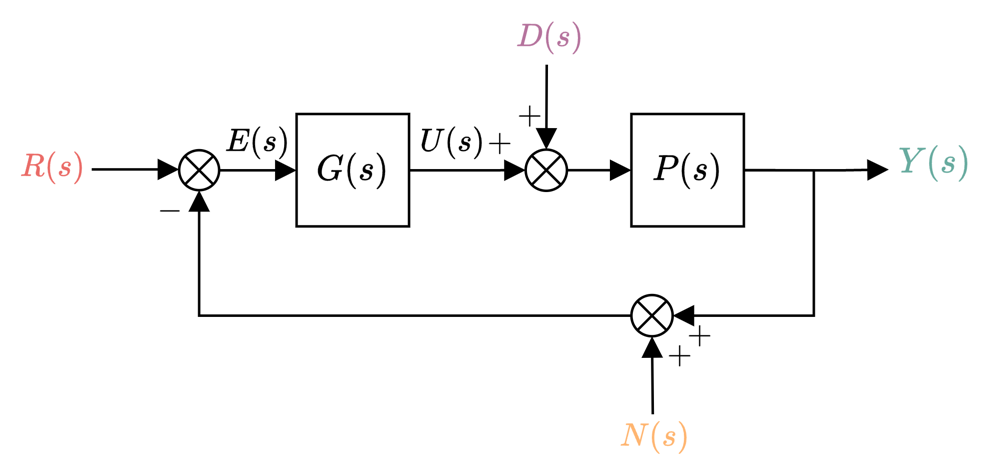

As before, we usually do not have a means of altering $P(s)$, but by adjusting $G(s)$, our only controllable degree of freedom, we can increase or decrease the effects of external signals on any other signal in our system. This will be shown in a subsequent section.

### 8.3.3 Loop transfer function

We define the **loop transfer function** as the transfer behaviour around the entire feedback loop, starting from the signal exiting the summing junction at $E(s)$, to the point where the signal returns to the summing junction. For the *two-degree-of-freedom* system, our loop transfer function is defined as

$L(s)=P(s)G(s)H(s)$.

For the *single-degree-of-freedom* system we effectively set $H(s)=1$. This causes our loop transfer function to reduced to the form of

$L(s)=P(s)G(s)$.

This is a useful transfer function that we will later use to analyse closed-loop stability and performance. However, we must be careful to not lose sight of signal $U(s)$, which resides between systems $G(s)$ and $P(s)$. This is also true for disturbance $D(s)$, which acts at the plant input.

### 8.3.4 Gang of four

Based on our understanding of block diagrams, we can determine our various input-output transfer function relationships. The external signals from before are:

- $R(s)$, representing the reference signal, 

- $D(s)$, representing a disturbance at the plant input, 

- $N(s)$, representing sensor noise, which is commonly modelled as a zero-mean signal with dominant high frequencies.

The signals that we would like to analyse are

- $Y(s)$, the plant output, which we are trying to control,

- $U(s)$, the control action that we will use to try control our system (and minimise to some extent in the time domain), and

- $E(s)$, the error between our desired and measured output, which we usually want to make small or zero.

The various transfer function relationships follow as

$Y(s) = \frac{P(s)G(s)}{1+P(s)G(s)}R(s)+\frac{P(s)}{1+P(s)G(s)}D(s)-\frac{P(s)G(s)}{1+P(s)G(s)}N(s)$,

$U(s) = \frac{G(s)}{1+P(s)G(s)}R(s)-\frac{P(s)G(s)}{1+P(s)G(s)}D(s)-\frac{G(s)}{1+P(s)G(s)}N(s)$,

$E(s) = \frac{1}{1+P(s)G(s)}R(s)-\frac{P(s)}{1+P(s)G(s)}D(s)-\frac{1}{1+P(s)G(s)}N(s)$.

Each term indicates the contribution that a particular external signal will make to the signal of interest. For example, disturbance $D(s)$ is multiplied by $\frac{P(s)}{1+P(s)G(s)}$ to get to its contribution towards $Y(s)$. What we also notice is that there are four unique transfer functions that capture all variations of contributions, namely

$\frac{P(s)G(s)}{1+P(s)G(s)}, \qquad \frac{P(s)}{1+P(s)G(s)}, \qquad \frac{G(s)}{1+P(s)G(s)}, \qquad \frac{1}{1+P(s)G(s)}$.

These four transfer functions are referred to as the **Gang of four **and play an important role in the control analysis and design process. We will refer to these transfer functions individually as shown in the table below.


$$\left.
\begin{array}{lcc}
\textbf{Name} \quad & \textbf{Symbol} \quad& \textbf{Transfer function}\\
\text{Sensitivity function} \quad & S(s) \quad& \frac{1}{1+P(s)G(s)}\\
\text{Load sensitivity function} \quad & PS(s) \quad& \frac{P(s)}{1+P(s)G(s)}\\
\text{Noise sensitivity function} \quad & GS(s) \quad& \frac{G(s)}{1+P(s)G(s)}\\
\text{Complementary sensitivity function} \quad & T(s) \quad& \frac{P(s)G(s)}{1+P(s)G(s)}
\\
\end{array}
\right.
$$


Note that the load sensitivity, $PS(s)$, is obtained by multiplying the sensitivity function, $S(s)$, by the plant $P(s)$. Similarly, the noise sensitivity, $GS(s)$, is obtained by multiplying $S(s)$ with the feedback controller $G(s)$. If we assess the relationship between the sensitivity function, $S(s)$, and the complementary sensitivity function, $T(s)$, we can notice a special relationship between the two based on

$S(s)+T(s)=\frac{1}{1+P(s)G(s)}+\frac{P(s)G(s)}{1+P(s)G(s)}=1$.

In other words, the sum of our sensitivity and complementary sensitivity functions will always equal unity for single-degree-of-freedom systems. This is why we refer to $T(s)$ as the *complementary* sensitivity function.

## 8.4 Feedback control objectives

As introduced when considering the purpose of the feedback control, feedback control problems fall into three categories: 

- tracking, 

- regulation, and 

- stability. 

While all three are coupled problems, we begin by analysing the first two separately.

### 8.5.1 Tracking

A **tracking **system is tasked with following external reference signal, $r(t)$, within some tolerance bands, without saturating the input, $u(t)$. Some examples include:

- A welding robot

- A satellite dish following a moving object

- An aircraft automatic landing system

In this scenario, the objective is to make the closed-loop output approach the reference signal within some tolerance ($|r(t)-y(t)|\leq \epsilon$), or $y(t)\approx r(t)$. By extension, this requires that $Y(s)\approx R(s)$ in some sufficient sense. Referring to the description of our output signal

$Y(s) = \frac{P(s)G(s)}{1+P(s)G(s)}R(s)+\frac{P(s)}{1+P(s)G(s)}D(s)-\frac{P(s)G(s)}{1+P(s)G(s)}N(s)$,

and considering only the effect of the reference signal on the output ($D(s)=N(s)=0$), we have the simplified relationship of 

$Y(s) = \frac{P(s)G(s)}{1+P(s)G(s)}R(s)=T(s)R(s)$.

Therefore, to achieve $Y(s) \approx R(s)$, we require $T(s) \approx 1$. In other words, in the absence of disturbance and noise effects, (somehow) forcing the complementary sensitivity function to be equal to approximately one achieves near-perfect tracking. As we cannot alter $P(s)$, the structure of $G(s)$ will be solely responsible to achieve this. 

We can assess the basic requirements of $G(s)$ using our understanding of the frequency response. Recall that $T(j\omega)=\lim_{s\rightarrow j\omega}T(s)$. The transfer behaviour is written out in full as

$T(j\omega)=\lim_{s\rightarrow j\omega}T(s)=\lim_{s\rightarrow j\omega}\frac{P(s)G(s)}{1+P(s)G(s)}=\frac{P(j\omega)G(j\omega)}{1+P(j\omega)G(j\omega)}$.

We can rewrite $T(j\omega)$ as

$T(j\omega)=\frac{P(j\omega)G(j\omega)}{1+P(j\omega)G(j\omega)}=\frac{P(j\omega)}{1/G(j\omega)+P(j\omega)}$.

Noting that we require $T(s)\approx 1$, and by extension $T(j\omega)\approx 1$, we therefore require $G(j\omega)\rightarrow \infty$ (formally, $|G(j\omega)|\rightarrow \infty$) to achieve this goal. In other words, our feedback controller, $G(s)$, must provide infinitely large gain at all frequencies (somehow). On the other hand, the transfer behaviour from $N(s)$ to $Y(s)$ is equivalent to that of $R(s)$ to $Y(s)$, so having $T(j\omega)\approx 1$ at all frequencies means that noise signal $N(s)$ will also pass through to the output signal with a gain of approximately one. As $N(s)$ is defined as being a high-frequency noise (a signal with predominantly high-frequency components), we certainly do not want to our output signal to be noisy at high frequencies (imagine an elevator that constantly shakes while moving up/down). For this reason, it makes sense to design $G(s)$ such that $|T(j\omega)|\approx 1$ for a suitable frequency band (which will be related to the user specifications for the closed-loop system), but then make the magnitude response of the complementary sensitivity function sufficiently small ($|T(j\omega)| \ll 1$ after some frequency point, in order to prevent the high-frequency noise from affecting the output signal significantly. A (very optimistic) depiction of this shown in the image below, where

$|T(j\omega)|\approx 1,~\forall \omega \leq \omega_0$,

and 

$|T(j\omega)| \ll 1,~\forall \omega > \omega_0$,

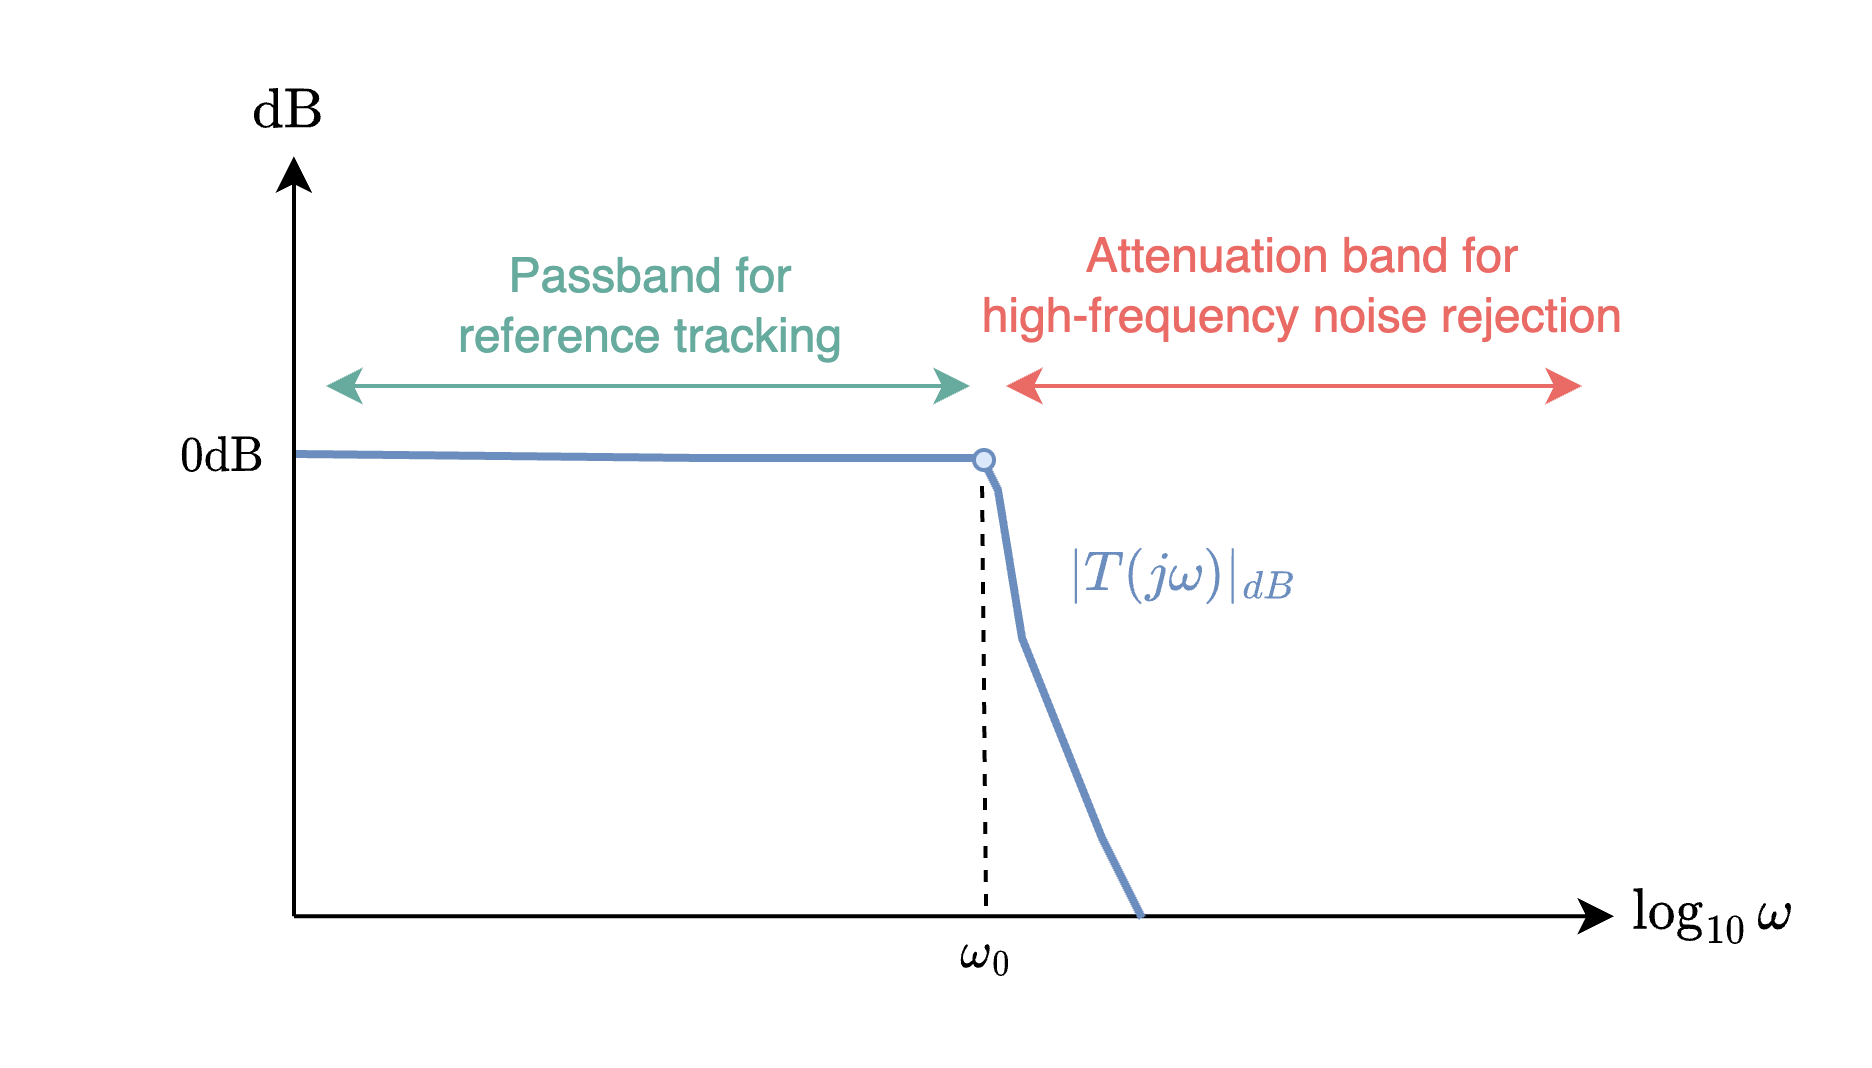

We still need to keep in mind that our control action, $u(t)$, has saturation limits, so our transfer behaviour from $R(s)$ to $U(s)$ should also be assessed. Reflecting on our description of the control action

$U(s) = \frac{G(s)}{1+P(s)G(s)}R(s)-\frac{P(s)G(s)}{1+P(s)G(s)}D(s)-\frac{G(s)}{1+P(s)G(s)}N(s)$,

and again considering only the effect of the reference signal on the control action ($D(s)=N(s)=0$), we obtain 

$U(s) = \frac{G(s)}{1+P(s)G(s)}R(s)$.

The frequency response relating $R(j\omega)$ to $U(j\omega)$ follows as

 $\frac{U(j\omega)}{R(j\omega)}=\frac{G(j\omega)}{1+P(j\omega)G(j\omega)}$,

which we can rewrite as

 $\frac{U(j\omega)}{R(j\omega)}=\frac{1}{1/G(j\omega)+P(j\omega)}$.

Therefore, having $|G(j\omega)|\rightarrow \infty$ implies that  $\frac{U(j\omega)}{R(j\omega)}\rightarrow\frac{1}{P(j\omega)}$. This means that we are at the mercy of $P(j\omega)$ when our feedback controller gain is infinitely large, as it dictates the frequency response behaviour from reference to control action. This is problematic when $P(j\omega)\rightarrow 0$ for some range of frequencies (which will occur at high frequencies when $P(j\omega)$ is strictly proper), resulting in $\left| \frac{U(j\omega)}{R(j\omega)}\right|\rightarrow\infty$. In this scenario, $u(t)$ is guaranteed to saturate, which will result in degraded system performance, as well as potential instability (more on this later). Note that the transfer behaviour from $N(s)$ to $U(s)$ has the same transfer behaviour of 

 $\frac{U(j\omega)}{N(j\omega)}=\frac{G(j\omega)}{1+P(j\omega)G(j\omega)}$,

which means that sensor noise will also be amplified by $\left|\frac{1}{P(j\omega)}\right|$ when making its way to the control signal. This results in a noisy, oscillatory control action when $\left|\frac{1}{P(j\omega)}\right|$ is large, which can result in degraded controller performance and saturation.  

Based on the above-mentioned issues, we will aim to keep $\left|\frac{U(j\omega)}{R(j\omega)}\right|$ as small as possible, subject to the other specifications of our control system.

#### Example

Consider the simple uncertain system of $P(s)=\frac{5\pm 2}{s+10}$. In other words, our open-loop system is a first-order system with a gain value that is somewhere within the set of $[3,7]$. This could be as a result of time-dependent parameter variations, or possibly some nonlinear element in our system. If we now want the output of our system, $Y(s)$, to equal the applied reference signal, $R(s)$, then we can make use of a feedback controller $G(s)$, to adjust the behaviour of the closed-loop system, as shown below.

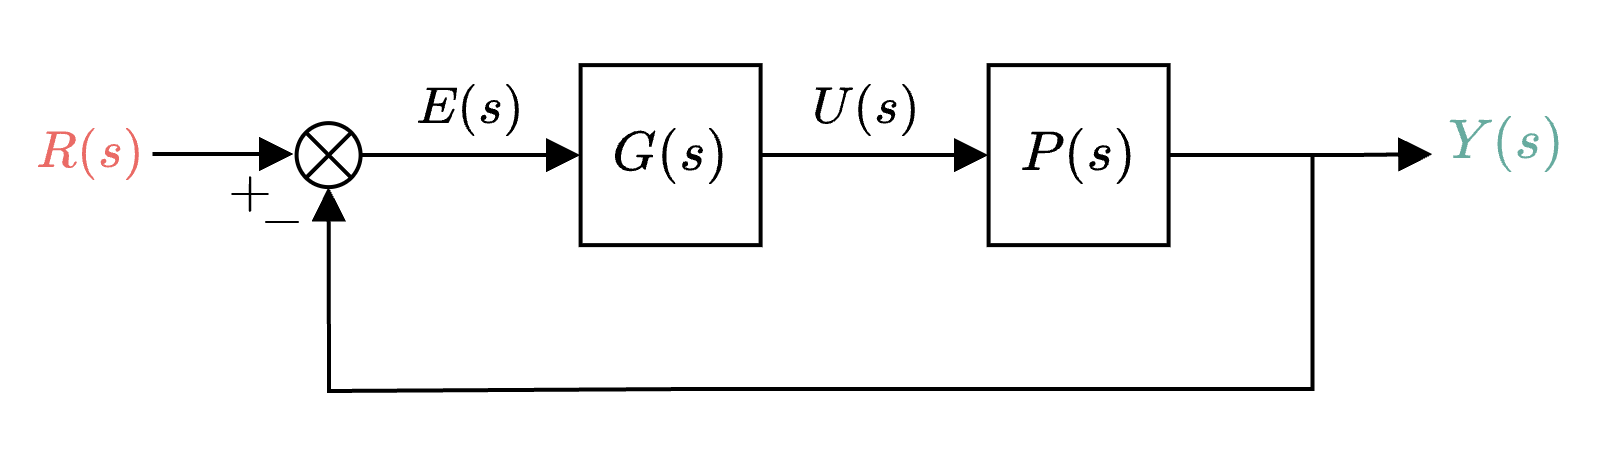

Let us consider $G(s)$ as a pure gain term to keep things simple, namely $G(s)=K$. We will also assume that the reference signal is $R(s)=1/s$. We can simulate the effect of increasing $K$ on our set of plants using the code below.

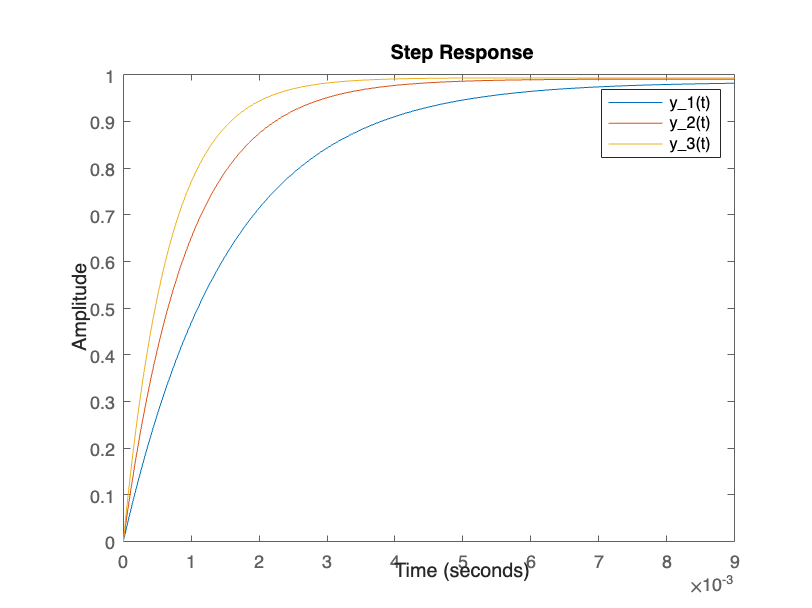

clear 
s = tf('s');
P1 = 3/(s+10);
P2 = 5/(s+10);
P3 = 7/(s+10);

G = 212.1;

T1 = feedback(P1*G,1);
T2 = feedback(P2*G,1);
T3 = feedback(P3*G,1);

figure,hold on
step(T1),step(T2),step(T3)
legend('y_1(t)','y_2(t)','y_3(t)')

We should observe that increasing the gain of feedback controller, $G(s)=K$ reduces the settling time of all three systems, as well as improves the steady-state tracking behaviour of $r(\infty)-y(\infty)$. However, as a consequence of increasing the controller gain, we also must incur larger control action, as shown below, which may be subject to saturation constraints.

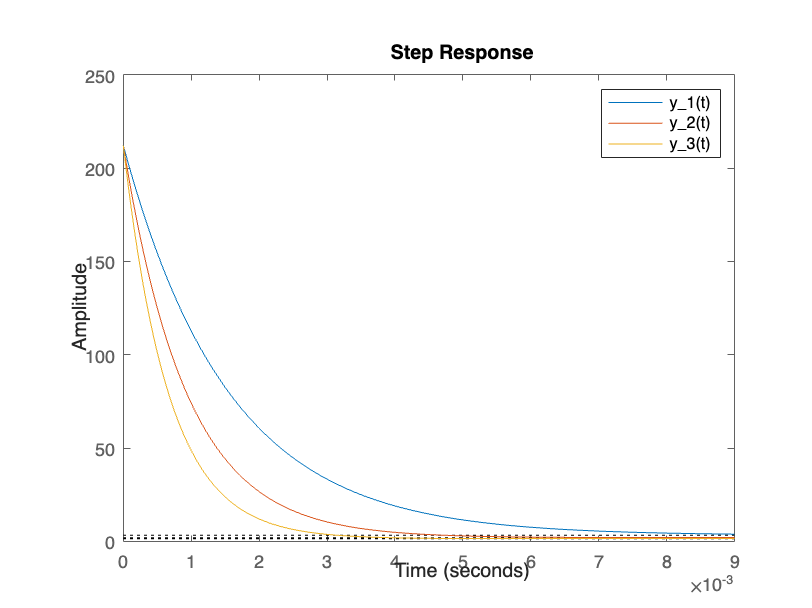

GS1 = feedback(G,P1);
GS2 = feedback(G,P2);
GS3 = feedback(G,P3);

figure,hold on
step(GS1),step(GS2),step(GS3)
legend('y_1(t)','y_2(t)','y_3(t)')

We can also visualise the behaviour of our closed-loop system using the frequency response. The code below shows the Bode magnitude response of $T_i(s)$.

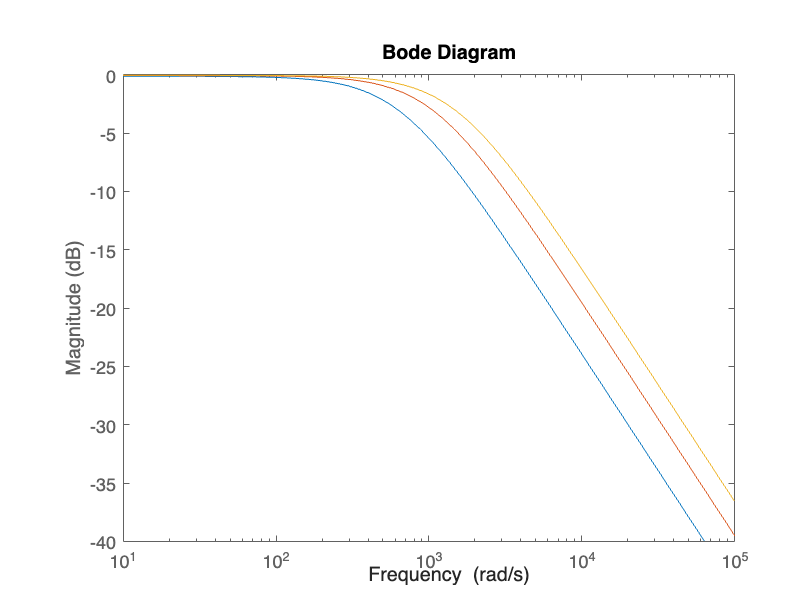

figure,hold on
bodemag(T1),bodemag(T2),bodemag(T3)

The behaviour of $|T_i(j\omega)|$ matches that of a low-pass filter, where the bandwidth increases as the gain of $G(s)$ is increased — resulting in the shorter settling times. This should not be too surprising, as we have already shown that increasing the loop gain sufficiently results in $Y(s)\approx R(s)$.

We can also visualise the magnitude response of $GS_i(s)$, which gives us an indication of the gain from reference to plant input (equivalent to the noise sensitivity).

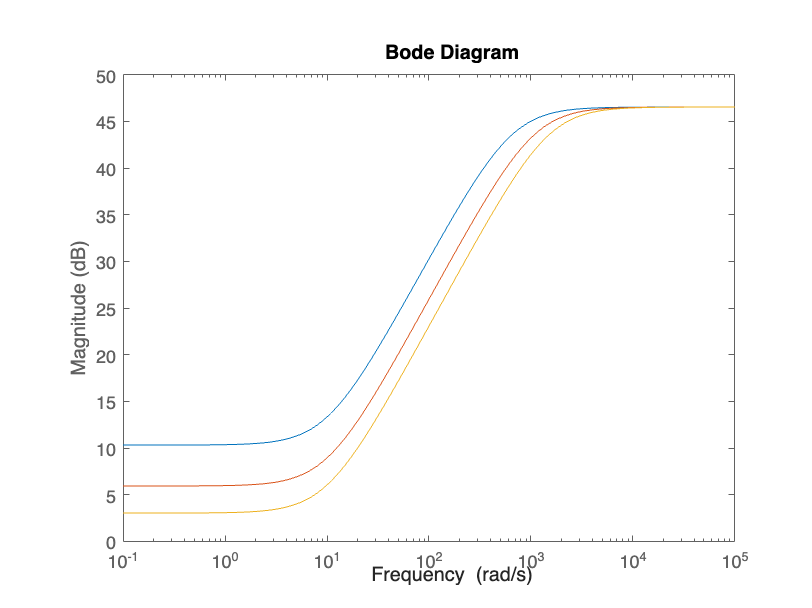

figure,hold on
bodemag(GS1),bodemag(GS2),bodemag(GS3)

The resulting plots show that there is significant gain at high frequencies ( $46$ dB!), which is resulting in large control actions when the reference signal is applied to the system. Note that in this simple example we did not consider sensor noise. However, the large high-frequency gain of $GS_i(s)$ means that we would have serious noise problems if we applied this control scheme on a real-world system. We will cover "correct" control design in **Chapter 11**.

### 8.4.2 Regulation

A **regulation **(also known as disturbance rejection) system is tasked with reducing/eliminating the effect of external disturbances, $d(t)$, on the system output, $y(t)$. Some examples include:

- Vehicle speed control with unknown wind and road gradient changes

- Air conditioning of a room when doors/windows are continuously opened and closed.

- Fulling the cistern of a toilet after flushing.

In this configuration, the reference signal, $r(t)$, is constant (often just zero) and plays no dynamic role in the control system. However, immeasurable disturbance, $d(t)$, enters the system at the plant input and can have an undesirable effect on the plant output. For this reason, we want to minimise the effect of $d(t)$ on $y(t)$, and by extension, the effect of $D(s)$ on $Y(s)$. Referring again to our description of the output signal

$Y(s) = \frac{P(s)G(s)}{1+P(s)G(s)}R(s)+\frac{P(s)}{1+P(s)G(s)}D(s)-\frac{P(s)G(s)}{1+P(s)G(s)}N(s)$,

and considering only the effect of $D(s)$ on $Y(s)$ (implying setting $R(s)=N(s)=0$), we have the simplified relationship of 

$Y(s) = \frac{P(s)}{1+P(s)G(s)}D(s)=PS(s)D(s)$.

Therefore, for disturbance $D(s)$ to have no effect on system output $Y(s)$, we require $PS(s)\rightarrow 0$. While we cannot alter $P(s)$, we have some control over $S(s)$, via $G(s)$, so if we make $S(s)\rightarrow 0$, then it follows that $P(s)S(s)\rightarrow 0$. 

We can assess the basic requirements of $G(s)$ using our understanding of the frequency response. Recall that $S(j\omega)=\lim_{s\rightarrow j\omega}S(s)$. The transfer behaviour is written out in full as

$S(j\omega)=\lim_{s\rightarrow j\omega}S(s)=\lim_{s\rightarrow j\omega}\frac{1}{1+P(s)G(s)}=\frac{1}{1+P(j\omega)G(j\omega)}$.

We require $S(s)\rightarrow 0$, and by extension $S(j\omega)\rightarrow 0$, therefor $G(j\omega)\rightarrow \infty$ (formally, $|G(j\omega)|\rightarrow \infty$) achieves this goal. In other words, our feedback controller, $G(s)$, must provide infinitely large gain at all frequencies in order to completely reject disturbances at the plant input.

We again run into the same issue as before when $|G(j\omega)|\rightarrow \infty$, where sensor noise is amplified by $\left|\frac{1}{P(j\omega)}\right|$ when making its way to the plant input, based on 

$\frac{U(j\omega)}{N(j\omega)}=\frac{G(j\omega)}{1+P(j\omega)G(j\omega)}$.

Additionally, we end up passing the high-frequency noise from $N(s)$ to $Y(s)$ when $|G(j\omega)|\rightarrow \infty$ for all frequencies.

### 8.4.3 Tracking error

Many real-world systems require both tracking and regulation consideration. For example, an aircraft taking off from a runway must follow a trajectory (tracking) whilst rejecting unmeasured wind disturbances (regulation). If we reformulate our analysis to assess the **tracking error **given by

$E(s) = \frac{1}{1+P(s)G(s)}R(s)-\frac{P(s)}{1+P(s)G(s)}D(s)-\frac{1}{1+P(s)G(s)}N(s)$,

we see that setting $|G(j\omega)|\rightarrow \infty$ seems to still solve our tracking and disturbance rejection problems "perfectly". That is, even when $R(s)$ and $D(s)$ are simultaneously non-zero, achieving infinitely large feedback gain (by making $|G(j\omega)|\rightarrow \infty$) results in $E(s)\rightarrow0$, which implies $Y(s)\rightarrow R(s)$, based on 


$$E(s)=R(s)-Y(s)$$


when the zero-mean measurement noise is $N(s)=0$. However, we are still expecting to have an infinitely large control action and noisy output signal, which is problematic for any real-world system. 

We will see later that stability also becomes a limiting factor in the amount of gain that our feedback controller can have. As part of the control design process, we will have to eventually accept that there is a trade-off between the amount of gain our loop transfer function can have and the stability and realisabilty of our control system.

### 8.4.4 Cost of feedback

To summarise from the previous sections, infinitely large feedback controller gain seems to solve all control problems, but this results in unrealistic control signals that can result in degraded system performance, noisy output signals that will oscillate at high frequencies, as well as instability (although we still need to show this). This is referred to as the **cost of feedback **— basically, there is no such thing as a free lunch! Instead, we will have to accept that we cannot achieve infinitely large feedback controller gain at all frequencies of interest, especially within the high-frequency range. 

Based on our previous assessment that $\frac{U(j\omega)}{N(j\omega)}$ and $\frac{U(j\omega)}{R(j\omega)}$ tend to  $\frac{1}{P(j\omega)}$ when $|G(j\omega)|\rightarrow \infty$, we can also identify that this is not problematic when $P(j\omega)$ is not small, which is common for systems in the low-frequency range. Therefore we have realistic hope to have large gain at low frequencies, resulting in $T(j\omega)\approx 1$and $S(j\omega)\approx 0$ for sufficiently small $\omega$. For higher frequencies, we rather design $G(s)$ such that $T(j\omega)\approx 0$and $S(j\omega)\approx 1$, as this reduces the effect of noise amplification whilst also reducing the control action required. This constitutes a fundamental trade-off within our control system — our system is effectively in open loop at sufficiently high frequencies as a result of $P(j\omega)\approx 0$, but within the low- to mid-frequency range when $|P(j\omega)|\gg0$, $G(s)$ has some control over the closed-loop transfer behaviour, depending on the frequency.

A realistic translation of the cost of feedback is shown in the Bode magnitude response below. 

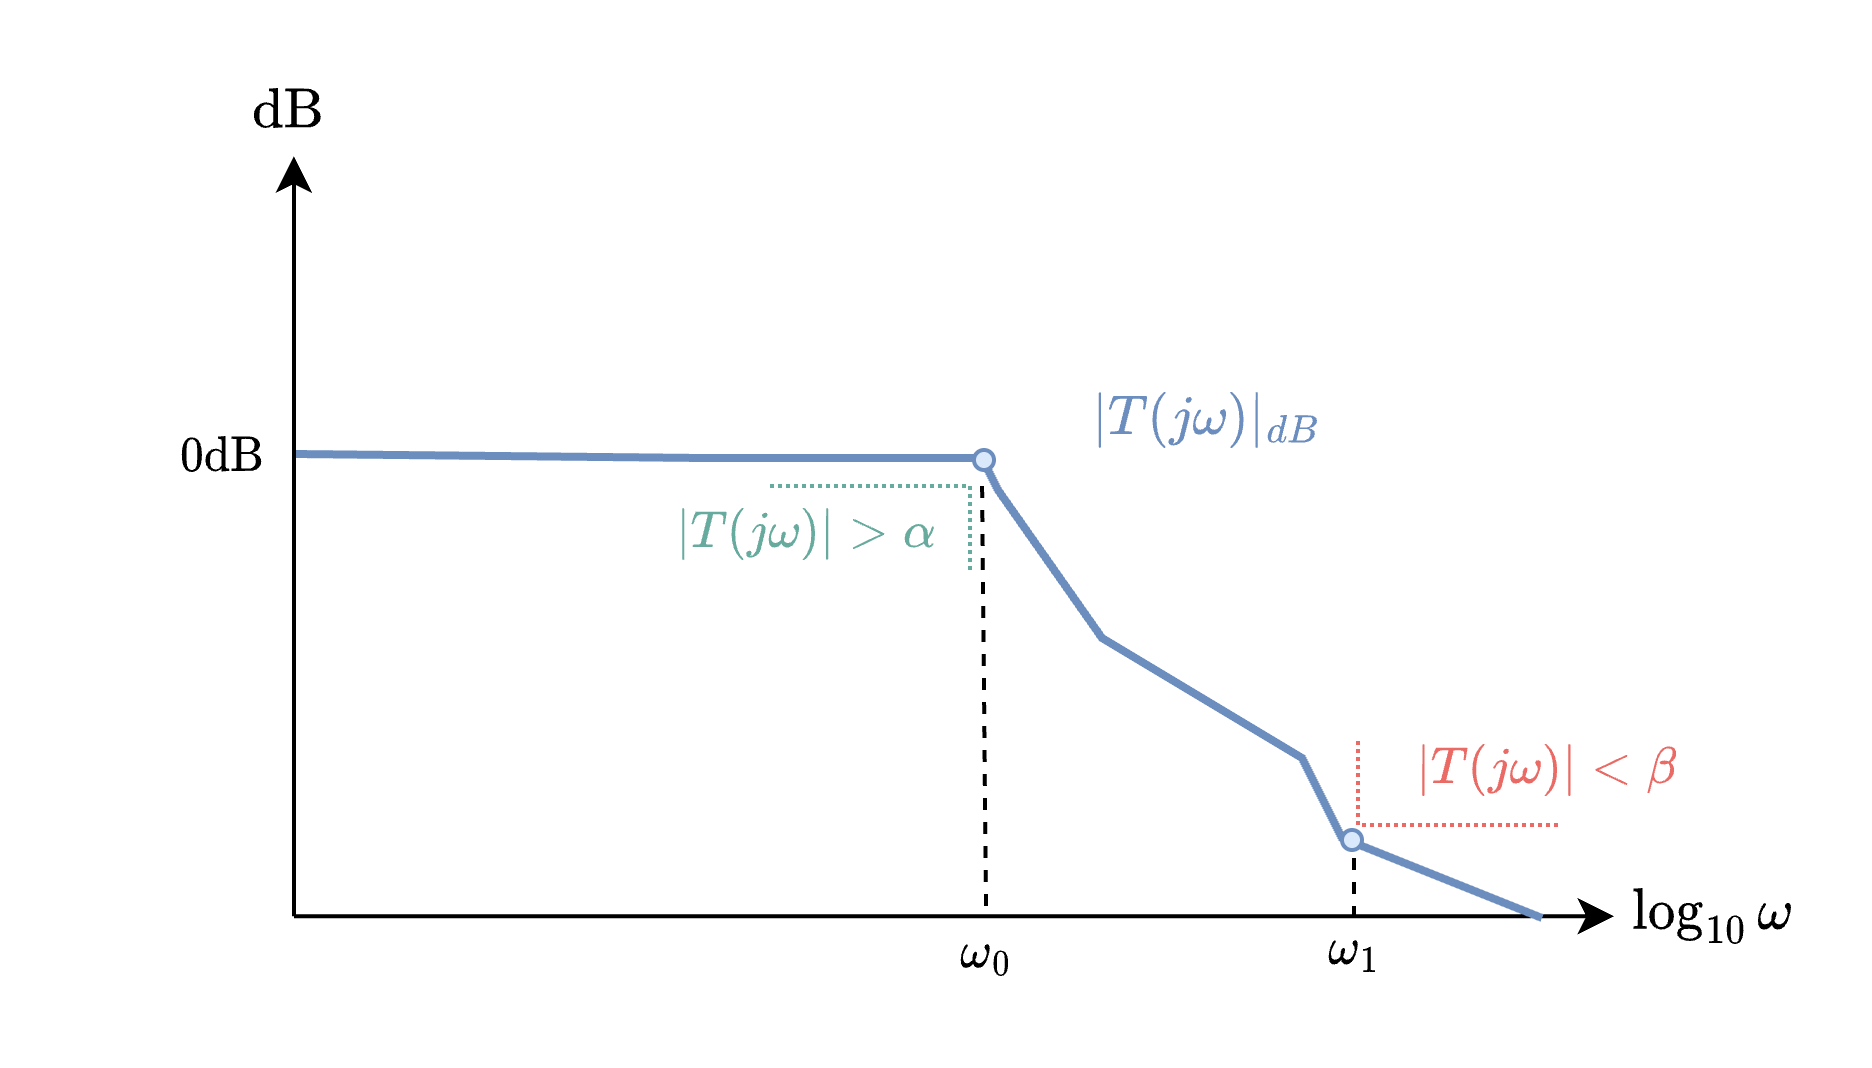

We can realistically keep $|T(j\omega)|\approx 1$ for low frequencies, which is represented by $|T(j\omega)|> \alpha$ up to frequency $\omega_0$, where $\alpha\leq1$. However, at high frequencies we enforce $|T(j\omega)|\ll 1$ by making use of the design constraint of $|T(j\omega)|< \beta$ for $\omega\geq \omega_1$, where $\beta<\alpha$. The mid frequencies between $\omega_0$ and $\omega_1$ are less obvious to cater for at this stage, but it is desirable that $|T(j\omega)|$ reduces rapidly for $\omega>\omega_0$, so as to meet the high-frequency requirement. 

We still need to relate the requirements of $|T(j\omega)|$ to that of $G(j\omega)$ (our feedback controller, which is the only part of the control system that we can adjust), which is currently unclear. Additionally, how $\alpha$, $\beta$, $\omega_0$, and $\omega_1$ from the example above are determined is also currently unclear. We will begin to cover unwrap this in **Chapter 10**, followed by earnest consideration in **Chapter 11.**